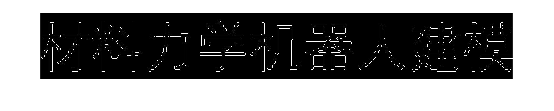

close all; clear all; clc;
%IMG = rgb2gray(imread('testsave.jpg')); % transfer to grayscalce pic
IMG = imread('testsave (1).jpg');
IMG = IMG - imerode(IMG,[0 1 0 ; 1 1 1 ; 0 1 0]); 
figure; 
imshow(IMG);     

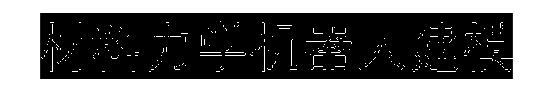


%IMG=imrotate(IMG,90);
IMG = im2bw(IMG,0.5);
%w IMG=~IMG;
figure;
imshow(IMG);

% IMG = bwmorph(IMG,'thin');
% IMG = bwmorph(IMG,'spur',2);
% figure;
% imshow(IMG);
% 
% IMG=bwmorph(IMG,'remove');
% IMG=bwmorph(IMG,'thin');
% IMG=bwmorph(IMG,'clean');
% figure;
% imshow(IMG);

IMG1=IMG;
[m,n]=size(IMG);
IMG0=zeros(size(IMG));
[row,col]=find(IMG,1);
C=[row,col]

C =    166     1


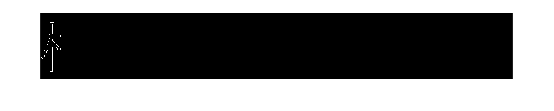

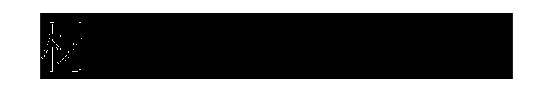


for i=1:2
    [C00,IMG00]=charcontour_get3(IMG1);%提取的轨迹的图像导出
    X = C00(:,1); % row of the contour
    Y = C00(:,2); % column  of the contour
    sqIndex = 1:size(C00(:,1),1); % freeman chain code index, used to determine the plotting sequence
    xx = smooth(X); % xx has the same dimension as X.
    yy = smooth(Y);
    IMG0=IMG00+IMG0;
    C00=[xx,yy];
    C=[C;C00];
    figure
    imshow(IMG0)
    
    IMG1=linedelete(IMG1,IMG00);
%     figure
%     imshow(IMG1)
    
%     IMG1=bwmorph(IMG1,'thin');
%     IMG1=bwmorph(IMG1,'clean');
    %IMG1 = bwmorph(IMG1,'spur',5);
%     figure;
%     imshow(IMG1);
end

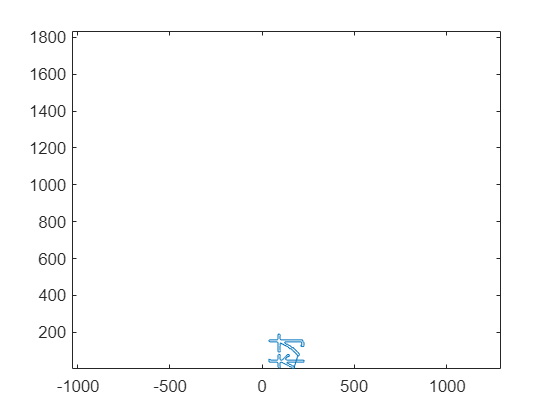

figure
plot(C(:,1),C(:,2)),xlim([1,m]),ylim([1,n]),axis equal

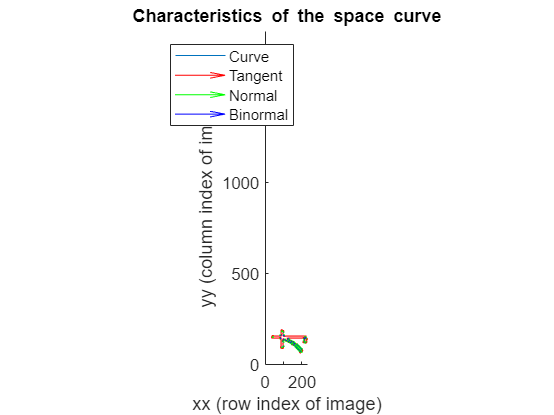


zz = zeros(size(xx,1),1);
[T,N,B,k,t] = frenet(xx,yy,zz);
figure
line(xx,yy,zz), hold on
axis([0,m,0,n,0,max(m,n)]);
axis equal
quiver3(xx,yy,zz,T(:,1),T(:,2),T(:,3),'color','r')
quiver3(xx,yy,zz,N(:,1),N(:,2),N(:,3),'color','g')
quiver3(xx,yy,zz,B(:,1),B(:,2),B(:,3),'color','b')
legend('Curve','Tangent','Normal','Binormal')
title('\bf{Characteristics of the space curve}');
xlabel('xx (row index of image)');
ylabel('yy (column index of image)');

% plot3(C(:,1),C(:,2),1:length(C))
% C2=contour_get(IMG2);
% figure
% imshow(C2)
% 
% 
% IMG3=linedelete(IMG2,C2);
% figure
% IMG3=bwmorph(IMG3,'clean');
% imshow(IMG3)

% IMG3=bwmorph(IMG3,'thin');
% figure;
% imshow(IMG3);
% 
% C3=contour_get(IMG3);
% figure
% imshow(C3)

% IMG = imerode(IMG,[0 1 0 ; 1 1 1 ; 0 1 0]);
% figure; 
% imshow(IMG);
